clear vars; close all; clc
format long
global A B C G P Z fre nn gamma x_eq tau 

%% Network settings
nn = 3;           % number of ring cells
flag = 2;         % 0 - regular ring, 1 - NONregular network, 2 - directed network

%% Parameter settings
mp_gamma = 1.1;   % multiplicator of parameter gamma
mp_tau = 1.0;     % multiplicator of parameter tau

%% Simulation settings 
ifi = 0;          % initial phase (if needed)
tend = 1000;      % simulation time 

%% MHB settings
Beta = 3;         % feasible region for amplitudes and offset
NumOfStP = 10;    % Amount of initial points for optimization

### Individual Dynamics

%% Centipide individual dynamics 

A = [1 -1 1; 1 0 0; -4 2 -3];
B = [0;0;1];
C = [0 0 1];
P = lyap(A',eye(length(A)));
Z = B'*P;

### Network Structure

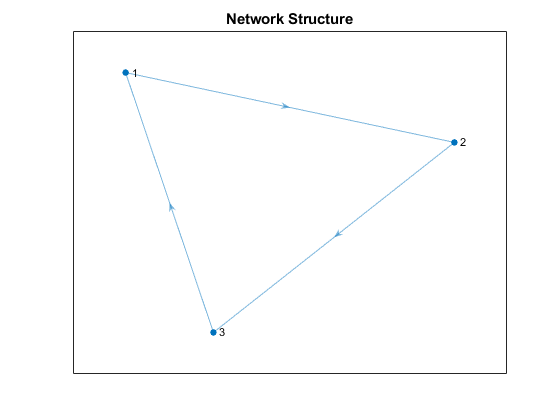

[G,n,offset] = NetworkStructure(nn,flag);

In=eye(n);

### Equilibrium point(s) and Linearizaton

syms x1 x2 x3  s zu
assume (x1, 'real')
assume (x2, 'real')
assume (x3, 'real')

x = [x1;x2;x3];

J(x) = jacobian(A*x- B*Z*x.^3);
eqp = solve((A*x- B*Z*x.^3==0),x);
x_eq = [double(eqp.x1); double(eqp.x2); double(eqp.x3)];
J0 = double(J(eqp.x1, eqp.x2, eqp.x3));
huzwitzCrit(J0)

System is Stable



H(s) = C*((s*eye(length(J0)) - J0)^-1)*B;
H(s) = simplify(H(s));

w = 0:0.0001:1;

L = double(H(1i*w'));

[nu,i] = min(real(L));

om_star = w(i);
disp(['Omega*: ',num2str(om_star)])

Omega*: 0.8146



gamma_min = -1/(2*nu);
disp(['Minimum coupling strength: ',num2str(gamma_min)])

Minimum coupling strength: 0.64812




BC = B*C;

AA = kron(In,(J0-gamma_min*BC));
BB = kron(gamma_min*G,BC);

eq1 = det(kronsum((AA + BB*zu),(AA'+ BB'*(1/zu))));
crit1 = double(solve(eq1==0,zu));
crit1m=[];
f1=[];
for i = 1:length(crit1)
    ei = eig(AA + BB*crit1(i));
    for ii = 1:length(ei)
        if abs(real(ei(ii)))<10e-6 && imag(ei(ii))>0 
            crit1m = [crit1m; crit1(i)];
            f1 = [f1; imag(ei(ii))];
        end
    end   
end

taus = sort((-1i*log(1./crit1m))./f1);
taus = real(taus(taus>0))

taus =    1.530414841294028
   1.531415095450595


disp('Critical time-delays for computed minimal coupling strength:')

Critical time-delays for computed minimal coupling strength:


taus = real(taus(taus>0)) % critical time-delays for computed gamma_min

taus =    1.530414841294028
   1.531415095450595


### Most rigth eigenvalue of linearized network

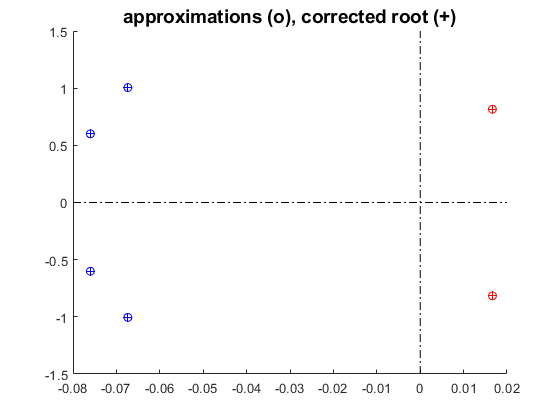

gamma =mp_gamma*gamma_min; 
tau = mp_tau*taus(1);

A0 = kron(In,(J0 - gamma*B*C));
A1 = kron(gamma*G,B*C);
hA = [0, tau];

tds = tds_create({A0, A1}, hA);
tds_check_valid(tds)
options=tdsrootsoptions;
options.minimal_real_part= -0.15;
[eigenvalues, N, size_eigenvalue_problem]=tds_charateristic_roots(tds, options);
figure(2)
eigenplot(eigenvalues)

eigenvalues.l1;
eigenvalues.l0;

ur = 0;
sum_ = 0;

for ur = 1:length(eigenvalues.l0)
   if real(eigenvalues.l0(ur))>10e-9
       sum_ = sum_ + 1;
   end
end
disp(['Amount of expected (!!!) stable oscillatory modes: ',num2str(sum_/2)])

Amount of expected (!!!) stable oscillatory modes: 1


## DDE Simulation Zero equlibria


IC = @centhist;
tic
options = ddeset('RelTol',1e-3);
sol = dde23(@centipide,tau,IC,[0, tend],options);
toc

Elapsed time is 4.094470 seconds.


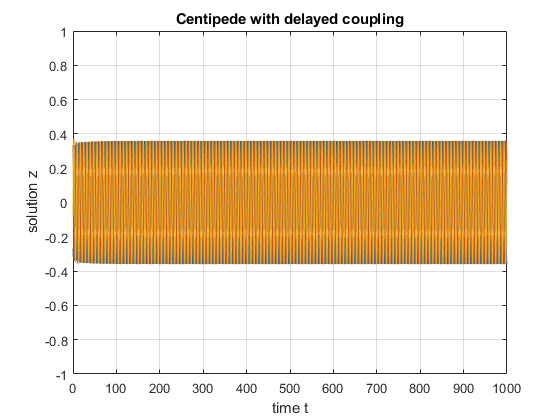

dde_z = kron(eye(n),Z)*sol.y;
dde_zs = dde_z + fliplr(offset)';
time = sol.x;

figure;
plot(time,dde_z)
title('Centipede with delayed coupling');
xlabel('time t');
ylabel('solution z');
ylim([-1 1])
grid on


[omega_s, T_s, amp_s, fi_s, DC_s] = osciprof(dde_z,time,n);

Frequency is equal to 0.82399
Period is equal to 7.6253
DC is 
   0.000743756486424
   0.000898109559880
  -0.001653812350312

Amplitudes are equal to 
   0.358457717102845
   0.358303364029390
   0.360855285939582

The phase shift is (RAD)
                   0
   4.184500484780074
   2.092644632818672

The phase shift is (DEG)
   1.0e+02 *

                   0
   2.397542171483452
   1.198997054812138




q_s = amp_s.*exp(1i*fi_s);
y_s = DC_s + q_s;
g_s = [fi_s;amp_s;DC_s;omega_s];


### Describing function and MHB

%% Transfer function for LTI part

%% Intitial Conditions
g0 = randn(3*nn+1,1);  
fre = abs(imag(eigenvalues.l1(1)));     % first guess of the oscillatory frequency

tic

rpts = RandomStartPointSet('NumStartPoints',NumOfStP);

[lbound,ubound] = boundsconst_fullsynch(g0,om_star,Beta);
ms = MultiStart('Display','iter','FunctionTolerance',1e-8,'XTolerance',1e-8);

opts = optimoptions(@fmincon,'Algorithm','interior-point','MaxFunctionEvaluations',120000);
problem = createOptimProblem('fmincon','x0',g0,...
    'objective',@CENcostfun,'lb',lbound,'ub',ubound,...
    'options',opts);


[xmin,fmin,flag,outpt,allmins] = run(ms,problem,rpts);


    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         1    1.627e-07       139      1544      6.85e-07
       2         1    2.922e-08        83       929     8.466e-07
       3         1    2.923e-08        49       554      2.56e-07
       4         1    1.624e-07       105      1170      4.13e-07
       5         1     3.03e-08        70       794      2.62e-07
       6         1    2.924e-08        72       805      2.56e-07
       7         1    2.865e-08        80       906     6.596e-07
       8         1    2.917e-08        87       972     4.011e-07
       9         1    2.846e-08        88       989     5.125e-07
      10         1    2.904e-08        93      1054     2.557e-07

MultiStart completed the runs from all start points.

All 10 local solver runs converged with a positive local solver exit flag.



toc

Elapsed time is 3.078891 seconds.


### Examine Stability 

GG = [allmins.X];
fval = [allmins.Fval];
[k,ii]=size(GG); i=1; ACC=[]; LAMDA=[];


### Reading solution


g = GG(:,8);

[g,q,omega,amp,fi,b] = ReadSolution_shifted(g,k);

Frequency is equal to 0.82422
Period is equal to 7.6232
DC is 
   1.0e-04 *

   0.839316005869733
   0.840287244160268
   0.838523741939361

Amplitudes are equal to 
   0.362551039470278
   0.362551138611668
   0.362551092704382

The phase shift is (RAD)
   3.119749562236234
   1.025354788036244
   5.214144044288219

The phase shift is (DEG)
   1.0e+02 *

   1.787484830539223
   0.587485018580079
   2.987484475109892




dDC = 100*norm(b-DC_s)/norm(DC_s)

dDC =      1.002768587580558e+02


dAmp = 100*norm(amp-amp_s)/norm(amp_s)

dAmp =    0.986549072048367


dOmega = 100*norm(omega-omega_s)/norm(omega_s)

dOmega =    0.027764741072611


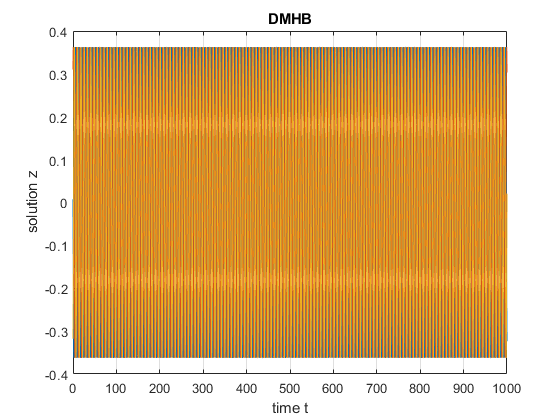



 %% Oscillations

[tiq,qsim] = Oscillations_shifted(amp,b,omega,ifi,fi,offset-offset,tend);

figure;
plot(tiq,qsim)
title('DMHB');
xlabel('time t');
ylabel('solution z');
grid on